# Ex 3-4: Histogram of Gradients

## Clean up environment

clc             % Clear console
clear variables % Clear workspace
close all       % Close figures

## Parameters

% Reference image
img1 = './images/car_smart1.jpg';

% Test image
img2 = './images/car_smart2.jpg';
img3 = './images/car_smart3.jpg';

## Compute HoG

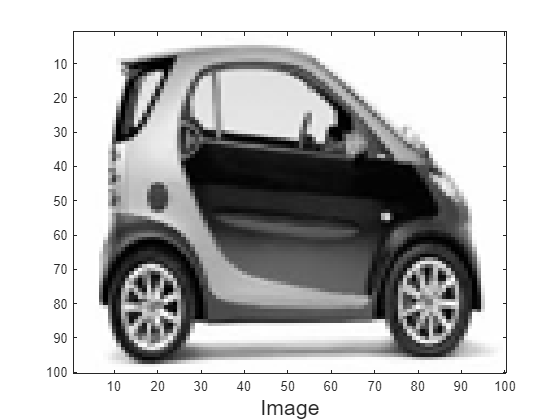

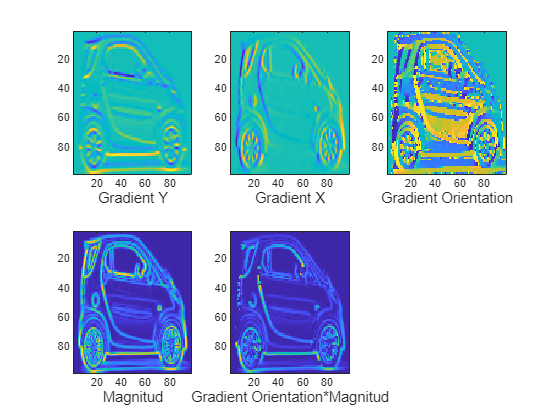

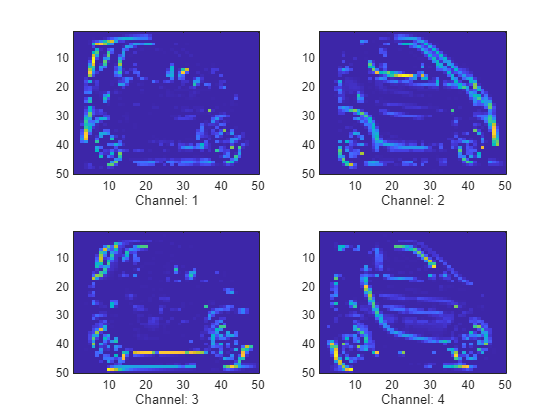

hog1 = fun_hog(img1);

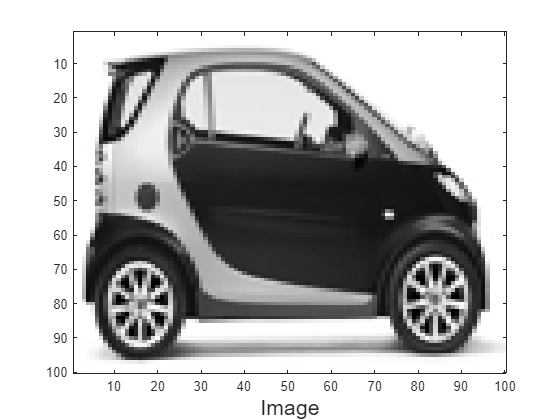

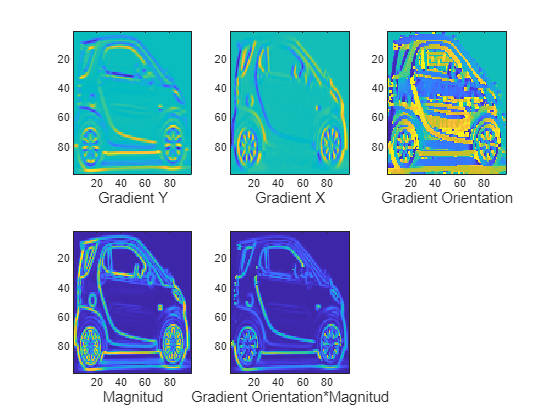

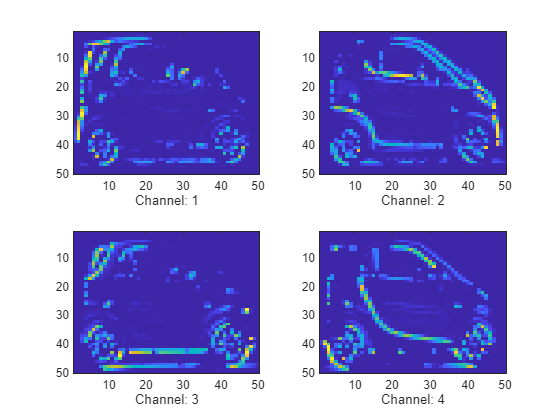

vec1 = hog1(:);

hog2 = fun_hog(img2);

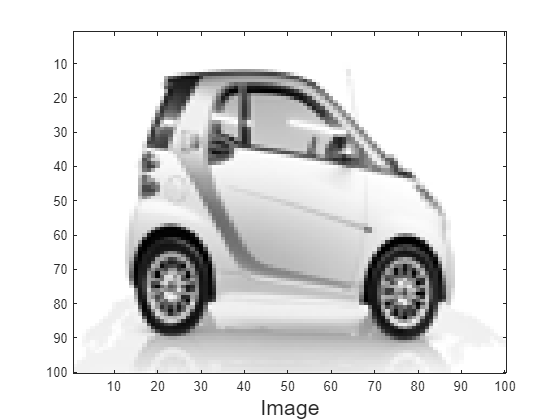

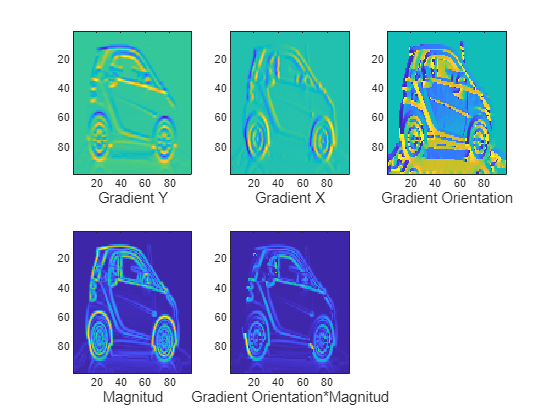

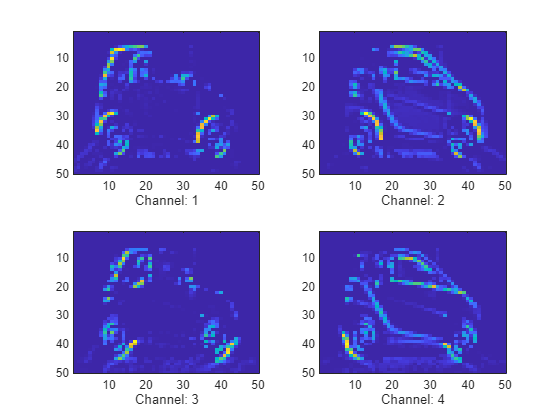

vec2 = hog2(:);

hog3 = fun_hog(img3);

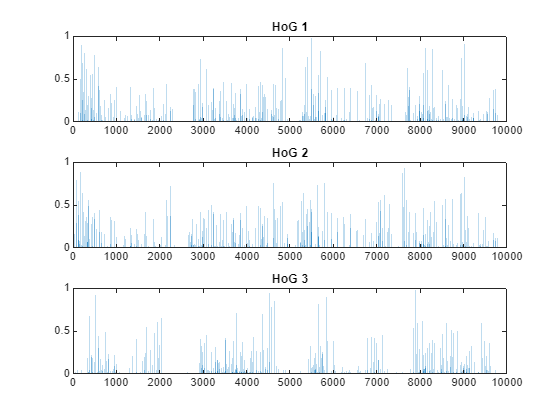

vec3 = hog3(:);

% TODO: Normalize vectors to within 0-1 range.
vec1 = normalize(vec1, 'range');
vec2 = normalize(vec2, 'range');
vec3 = normalize(vec3, 'range');

% Show vectors (histograms)
figure,
subplot(311), bar(vec1), title('HoG 1');
subplot(312), bar(vec2), title('HoG 2');
subplot(313), bar(vec3), title('HoG 3');


% TODO: calcular la similaridad entre los
% histogramas 1 y 2 (sim12) e histogramas
% 1 y 3 (sim13). Determine que imagen es 
% más similar a la imagen 1. Use como 
% similaridad la suma de la intersección min(v1,v2).
sim12 = sum(min(vec1, vec2));
sim13 = sum(min(vec1, vec3));

% Print similarities
fprintf('similarity 1-2: %.4f\n', sim12);

similarity 1-2: 217.8069


fprintf('similarity 1-3: %.4f\n', sim13);

similarity 1-3: 74.4177



% Classification
if (sim12 > sim13), fprintf('la imagen 1 y la imagen 2 son las mas similares \n'); end

la imagen 1 y la imagen 2 son las mas similares 


if (sim12 <= sim13), fprintf('la imagen 1 y la imagen 3 son las mas similares \n'); end